%resolution = [251,251];
%domain = [0, 2*pi;0, 2*pi];
%domain = [0.7, 1.3;0.7,1.3];
%range = diff(domain(2,:));
%delta = range./resolution(1);
%initialPosition = initialize_ic_grid(resolution, domain, 2);
%initGrid = zeros(length(initialPosition), 6);
%initGrid(:,1) = initialPosition(:,1);
%initGrid(:,3) = initialPosition(:,2);

p.C = 0.1;
p.z1Star = 0.95;
p.z4Star = -0.76095;
p.beta = 1.25;
p.gamma = 0.2;
p.b = 0.5;
k1 = [0.6437    0.3758    0.0134    0.2466    0.9713    0.9218
    0.6593    0.9886    0.5744    0.4189    0.9692    0.8826
    0.1492    0.3446    0.7777    0.6320    0.7434    0.0510
    0.7466    0.3434    0.9499    0.0955    0.5177    0.7749
    0.6414    0.6137    0.7030    0.3903    0.1645    0.1059
    0.2982    0.6184    0.1162    0.3220    0.9494    0.9054];

k2 = [0.4190    0.1917    0.1264    0.3554    0.0846    0.3168
    0.6480    0.4026    0.6050    0.3347    0.3157    0.2418
    0.5116    0.7868    0.2901    0.1775    0.9686    0.4910
    0.3338    0.2538    0.6265    0.0080    0.8736    0.5439
    0.7785    0.1095    0.6595    0.0104    0.9128    0.4055
    0.1354    0.9307    0.0677    0.5975    0.1699    0.7424];
knull = zeros(6,6);
epsilon = 0.1;
f = @(t,x) d_charneyDeVore(t,x,p, false, epsilon,k1, .1);
g = @(t,x) epsilon.*error(t,x, k2, 0.15);
lDerivative = @(t,x,e,eov) d_charneyDeVore(t, x,p,eov, e, knull, 0.);

dt = 1e-4;
time2 = 0:dt:10;
maxPlace = [1.14,0.,0., -0.91, 0., 0.];

resolution = [100,100];
domain = [0, 3 ; -3., 0];
initialPosition = initialize_ic_grid(resolution, domain, 2);
initGrid = zeros(length(initialPosition), 6);
initGrid(:,1) = initialPosition(:,1);
initGrid(:,4) = initialPosition(:,2);
timeSpan = [0,70];
stepSize = 70/25.;


ms = modelSensitivityGlobal(lDerivative, initGrid, resolution, timeSpan, stepSize, 'eoV');

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

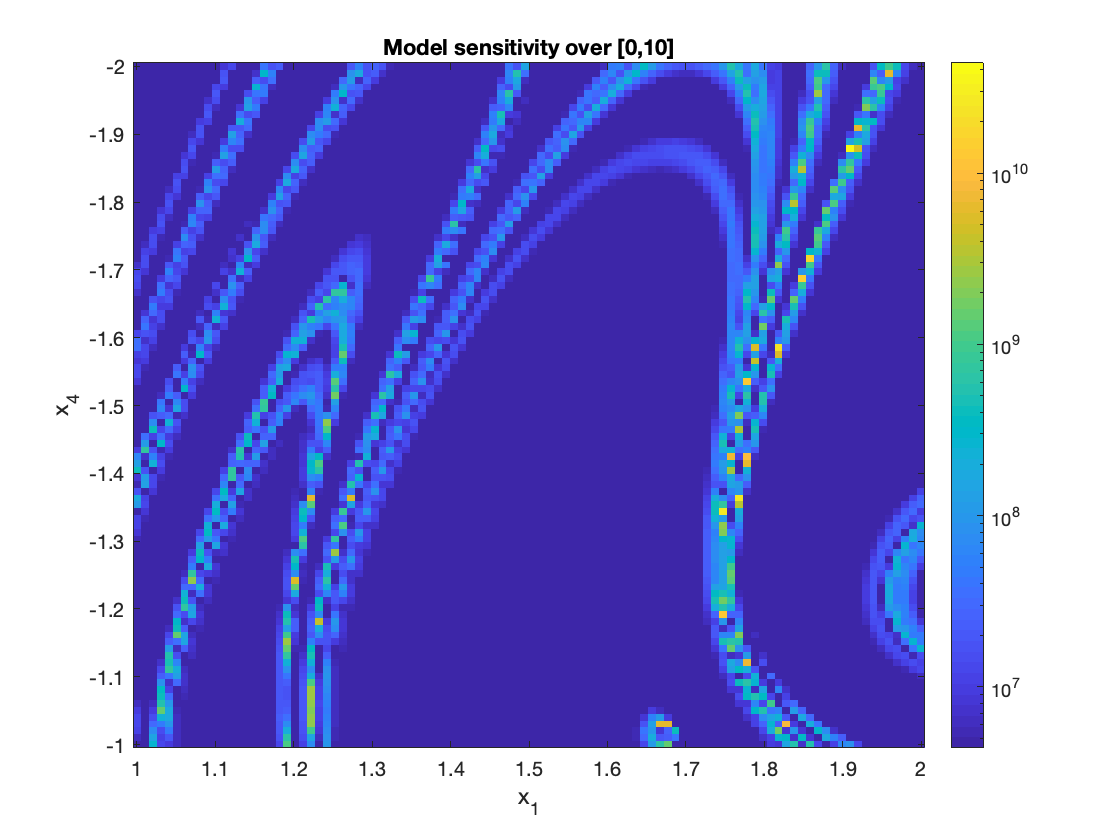

figure(2);
title('Model sensitivity over [0,10]');

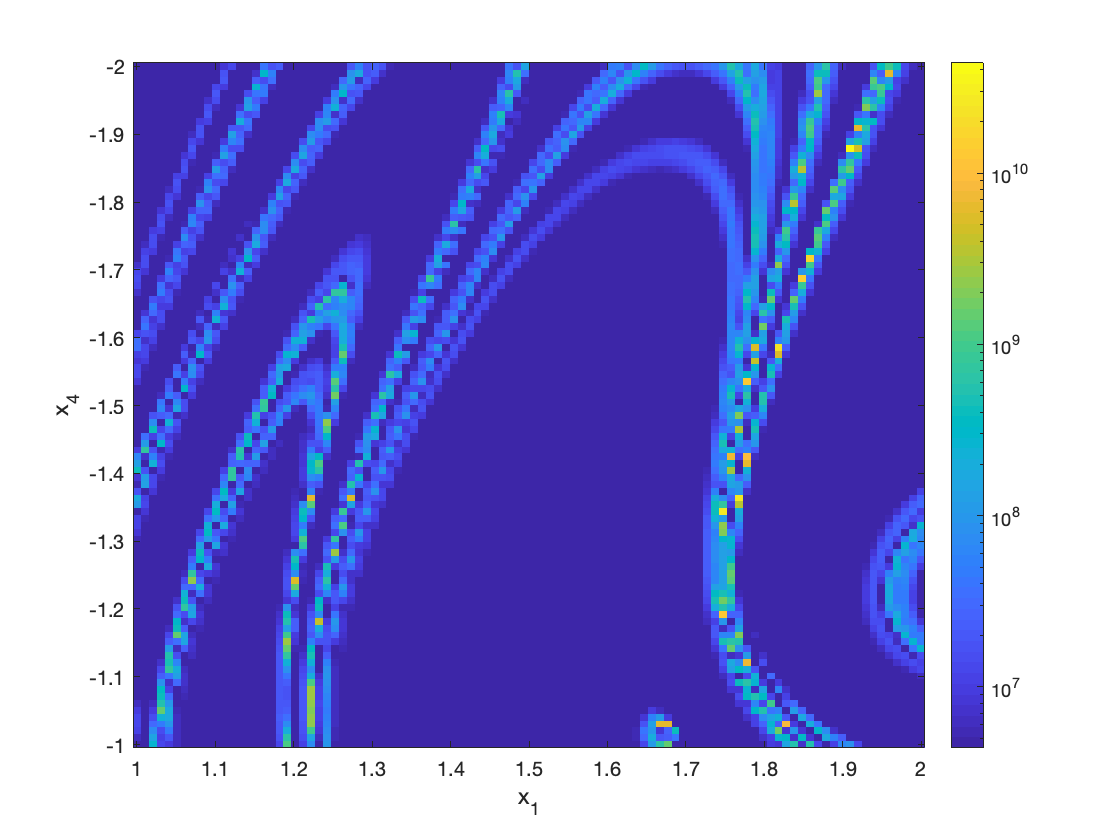

imagesc(domain(1, :), domain(2, :), ms);
xlabel('x_1');
ylabel('x_4');
set(gca, 'ColorScale', 'log');
colorbar;
saveas(gcf,'CDV_0_70.png');

timeSpan = [0,10];
stepSize = 10/10.;

ms2 = modelSensitivityGlobal(lDerivative, initGrid, resolution, timeSpan, stepSize, 'eoV');

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

   1

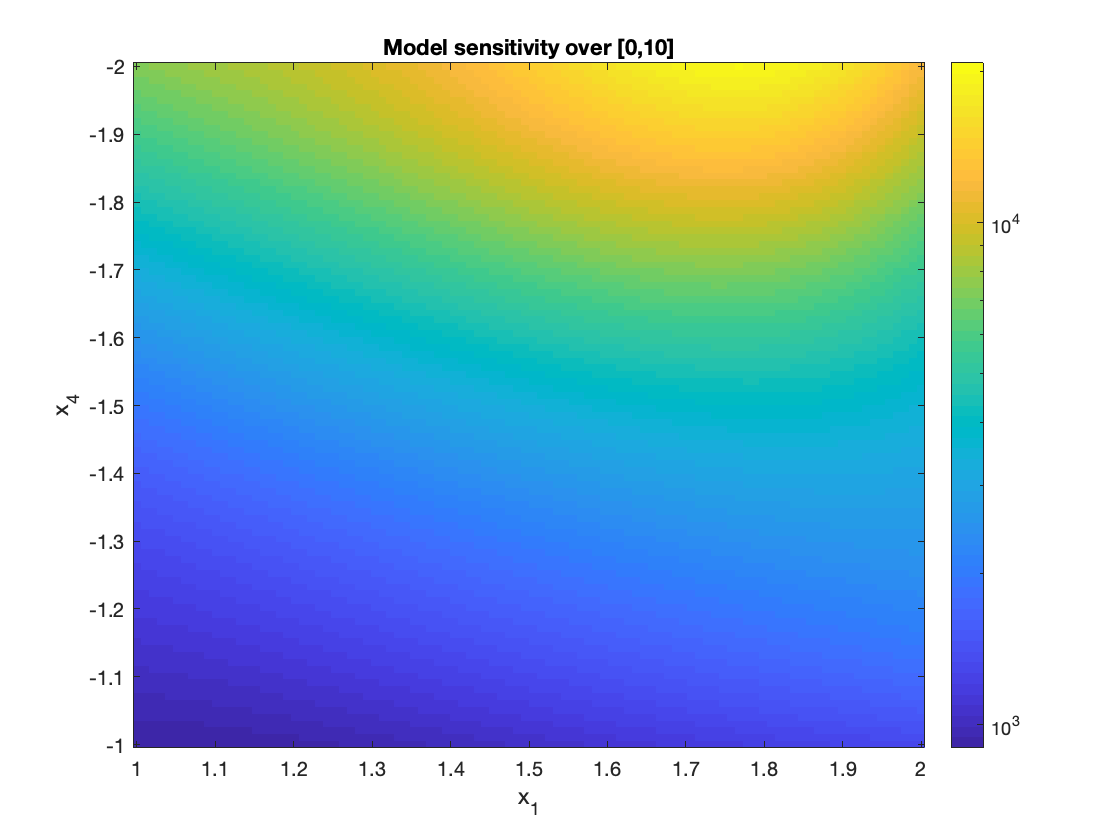

figure(3);
title('Model sensitivity over [0,10]');

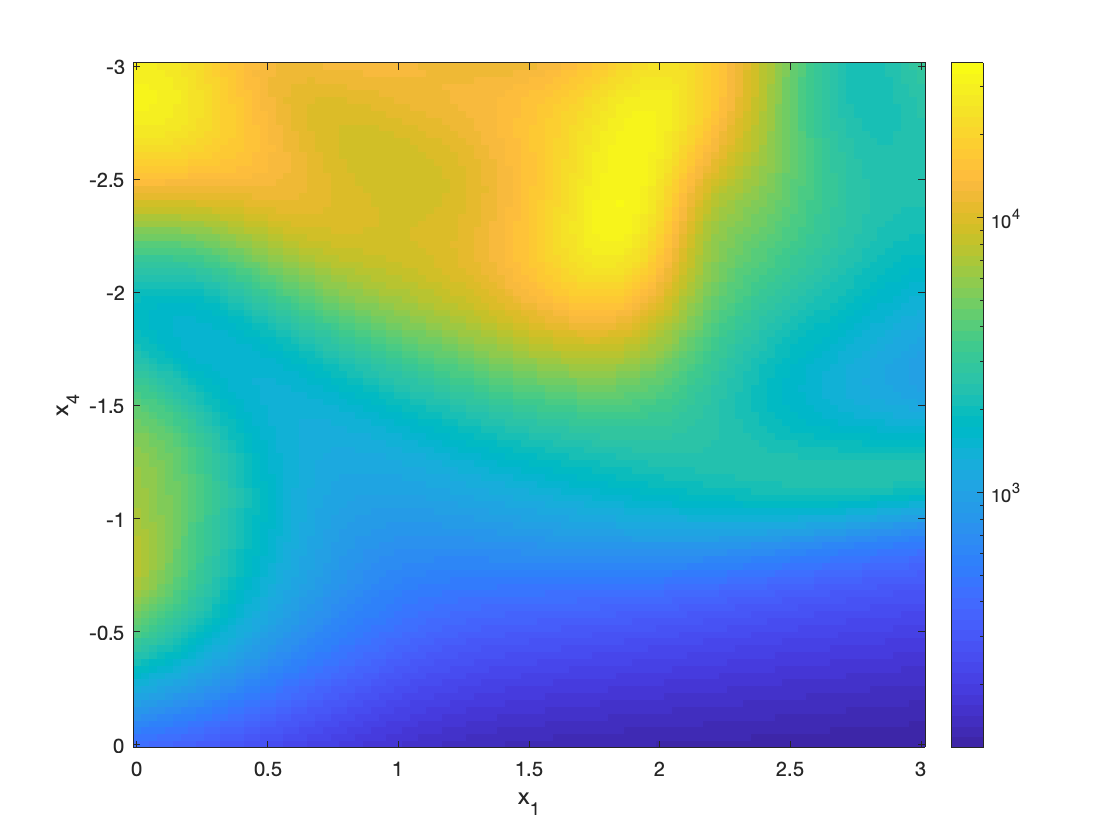

imagesc(domain(1, :), domain(2, :), ms2);
xlabel('x_1');
ylabel('x_4');
set(gca, 'ColorScale', 'log');
colorbar;
saveas(gcf,'CDV_0_10.png');

x1surf(initGrid(:,1),initGrid(:,4),ms);shading interp; axis equal;axis tight;colorbar; title('Model Sensitivity, CDV'); xlabel('X_1'); ylabel('X_4')

         0    6.2832
         0    6.2832



Error using surf (line 71)
Data dimensions must agree.

view([0 0 1]); axis equal; axis tight; shading interp;camlight
%[f_min f_max] = caxis;

[~,yfref] = ode45(@(t,y) d_charneyDeVore(t,y,p,false, 0, knull,0), time2, maxPlace); 
aggregate = zeros(size(yfref,1),100);
hold on;
[t, uncertestimate] = computeAlongTrajectoryVariationGeneralFullmodel(lDerivative, maxPlace, [0,10], 10/50. );
for i = 1:100
    yf = sde_euler(f,g,time2,maxPlace);
    diff = yf-yfref;
    aggregate(:,i) = sum(diff.^2,2);
    plot(time2, aggregate(:,i), '-.');
    
    %plot(t, sqrt(diff(:,1).^2+diff(:,2).^2), '.');
end
plot(time2, mean(aggregate,2), '-', 'linewidth', 4.);
plot(t, uncertestimate.*epsilon^2, '-', 'linewidth', 6.);


function errorvector = error(t, x,k, omega)
    z = 0.6; %length scale
    errorvector = zeros(6,1);
    for i=1:6
        ki = k(i,:)/z;
        %kprime = random(6,1).*z;
        errorvector(i) = sin(dot(ki,x))*sin(omega*t);
    end
end